bags = Dataset.get_dataset_bags("feb_2022/planar_arm_2in");
test_bag = bags(6);
test_bag_path = fullfile(test_bag.folder, test_bag.name);
fprintf("Testing with bag %s\nIn %s\n", test_bag.name, test_bag.folder)

Testing with bag localized-15psi_2022-02-03-22-39-04.bag
In /home/bf01/tagslam_ws/tagslam_root/src/continuum_mocap/bags/feb_2022/planar_arm_2in/localized


tag_ids = [6 7 8 9];

g_tags = repmat({eye(3)}, 1, 4);

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

tags = Tag(tag_ids, {}, muscle_ids, t_tags, "group", SE2());

% Create arm object
g_1 = SE2.hat([0, -base_offset_cm / 100, pi/2]);

rho = 1 * 0.0254;
g_o_1 = SE2.hat([0, rho, 0]); % Muscle 1
g_o_2 = SE2.hat([0, -rho, 0]); % Muscle 2
g_o = g_1 * inv(g_o_1); % Central muscle
g_o_muscles = {g_1; g_o * g_o_2};
l_0 = contraction_fit_poly(0);
arm_obj = Arm2D(g_o, g_o_muscles, l_0, 'plot_unstrained', false);

g_tag_offset = SE2.hat([0 0 -pi/2]);

% Create Measurement object
obj_measurement = Measurement(test_bag_path, [0, 15], tags(1), tags, arm_obj, 'group', SE2(), 'g_tag_offset', g_tag_offset);

         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
Warnin

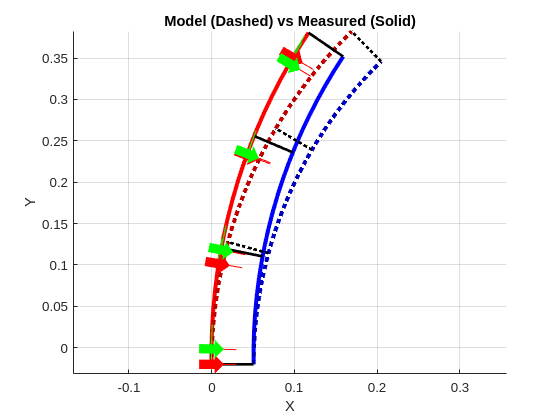

fig = figure();
obj_measurement.plot_measurement(axes);
title("Model (Dashed) vs Measured (Solid)");

bags = Dataset.get_dataset_bags("feb_2022/spatial_3muscle");
test_bag = bags(8);
test_bag_path = fullfile(test_bag.folder, test_bag.name);
fprintf("Testing with bag %s\nIn %s\n", test_bag.name, test_bag.folder)

Testing with bag localized-20psi_2022-02-06-19-53-17.bag
In /home/bf01/tagslam_ws/tagslam_root/src/continuum_mocap/bags/feb_2022/spatial_3muscle/localized


%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
experiment_tags = [6 7 8 15 10 11 14 9]; % Tags 6 to 9 
base_tag_id = 10;

% the muscles that these muscles are attached to (in the same order) 
tag_muscle_ids = [3 3 3 3 1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 15 20 25 30 35 40 45 50 55 60];

%% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = 0;

%% Construct pose matrices
% Transformations from world frame to each muscle

g_default_muscle_original = SE3.hat(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]);
g_default_muscle = SE3.hat(eul2rotm([0, pi/2 + deg2rad(4), 0], 'xyz'), [0 0 0]); % Frame corresponding to a muscle at the origin, pointing down

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_muscles = Arm3D.generate_g_muscles(rho, g_default_muscle_original, 3, muscle_angle);

% Set position of first muscle to actually be at the origin
% We want to shift *everything* uniformly regardless of its pose, therefore
% it'll be a left-action:
% g_shift * g_1 = g_neutral
% Therefore g_shift = g_neutral * inv(g_1)
% Additionally, we rotate by a global 180deg so that all 3 muscles are
% aligned correctly
g_muscle_shift = g_default_muscle_original * inv(g_muscles{1});

% Then left-apply g_shift to all transformations
g_o = g_muscle_shift * g_default_muscle_original;
g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);

arm_obj = Arm3D(g_o, g_muscles, contraction_fit(0), 'plot_unstrained', false);
arm_obj.n_spacers = 8;
tags = Tag(experiment_tags, repmat({eye(4)}, size(experiment_tags)), tag_muscle_ids, t_tags);

g_tag_offset = SE3.hat(eul2rotm([-pi/2, 0, 0], 'zyx'), [0; 0; 0.788 * 0.0254]);

% Create Measurement object
obj_measurement = Measurement(test_bag_path, [20, 0, 0], tags(5), tags, arm_obj, 'g_tag_offset', g_tag_offset);

         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
         at line 278 in /mathworks/devel/bat/B3p2/build/3p/derived/glnxa64/ros1/src/geometry2/tf2/src/buffer_core.cpp
Warn

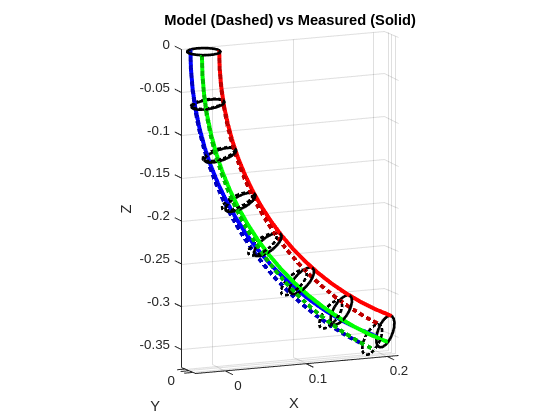

fig = figure();
obj_measurement.plot_measurement(axes);
view([-23.3684   12.3360]);
title("Model (Dashed) vs Measured (Solid)");